clc
clear aLL
% Define link lengths
L1 = 0;  % Length of the first link
L2 = 10; % Length of the second link
L3 = 5;  % Length of the linear (prismatic) link
L4 = 5;  % Length of the fourth link

% Define links for RRPRR configuration
L(1) = Link('revolute', 'd', 2, 'a', L1, 'alpha',  pi/2);   % Revolute joint
L(2) = Link('revolute', 'd', 0, 'a', L2, 'alpha', 0);       % Revolute joint
L(3) = Link('prismatic', 'theta', 0, 'a', 0, 'alpha', 0);   % Prismatic joint
L(3).qlim = [0, 10]; % Set movement limits for the prismatic joint
L(4) = Link('revolute', 'd', 0, 'a', L3, 'alpha', -pi/2);   % Revolute joint
L(5) = Link('revolute', 'd', 2, 'a', L4, 'alpha', 0);       % Revolute joint

% Create the robot
robot = SerialLink(L, 'name', 'RRPRR manipulator');
T = robot.fkine([0, pi/4, 0, -pi/4, 0])

 

T = 
         1         0         0     17.07
         0         1         0         0
         0         0         1     11.07
         0         0         0         1


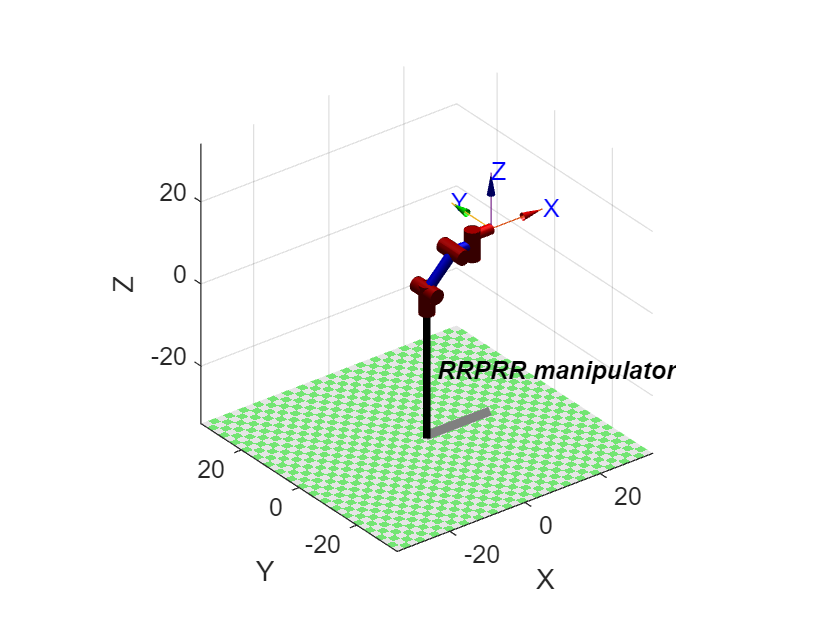

% Plot the robot in the initial position
robot.plot([0, pi/4, 0, -pi/4, 0]); % Initial configuration


 
q = robot.ikine(T, 'mask', [1 1 1 0 0 1])

q =     0.0000    0.1915   -0.0000    0.3906   -0.0000
